# File Name: Search_Registration_04_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Affine Transformations of 3-D Point Cloud

Read a point cloud into the workspace.

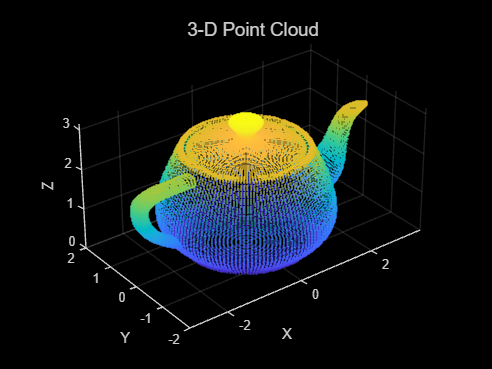

ptCloud = pcread('teapot.ply');


% Rotation of 3-D Point Cloud
%%%%%%%%%% TODO %%%%%%%%%%
% Create an affine transform object that defines a 45 degree rotation along the z-axis.
A = [cos(pi/4) sin(pi/4) 0 0; ...
    -sin(pi/4) cos(pi/4) 0 0; ...
    0 0 1 0; ...
    0 0 0 1];
tform = affine3d(A);

%%%%%%%%%% TODO %%%%%%%%%%
% Transform the point cloud.
ptCloudOut1 = pctransform(ptCloud,tform);

% Shearing of 3-D point cloud
% Create an affine transform object that defines shearing along the x-axis.
A = [1 0 0 0; ...
    0.75 1 0 0; ...
    0.75 0 1 0; ...
    0 0 0 1];
tform = affine3d(A);

%%%%%%%%%% TODO %%%%%%%%%%
% Transform the point cloud.
ptCloudOut2 = pctransform(ptCloud,tform);

% Display the Original and Affine Transformed 3-D Point Clouds
figure1 = figure('WindowState','normal');
axes1 = axes('Parent',figure1);
pcshow(ptCloud,'Parent',axes1);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3-D Point Cloud','FontSize',14)

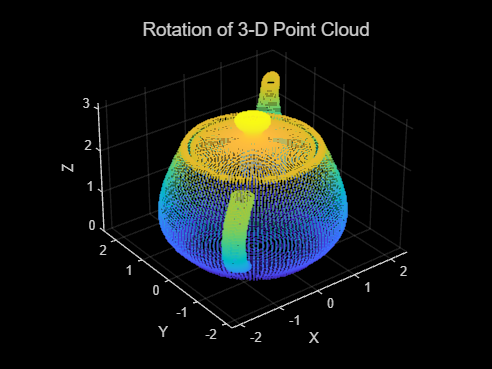


figure2 = figure('WindowState','normal');
axes2 = axes('Parent',figure2);
pcshow(ptCloudOut1,'Parent',axes2);
xlabel('X');
ylabel('Y');
zlabel('Z');
title({'Rotation of 3-D Point Cloud'},'FontSize',14)

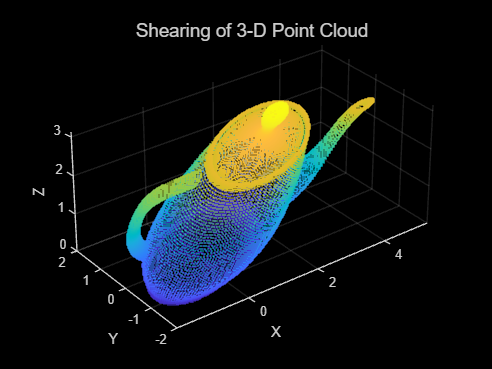


figure3 = figure('WindowState','normal');
axes3 = axes('Parent',figure3);
pcshow(ptCloudOut2,'Parent',axes3);
xlabel('X');
ylabel('Y');
zlabel('Z');
title({'Shearing of 3-D Point Cloud'},'FontSize',14)